ans = logical
   0


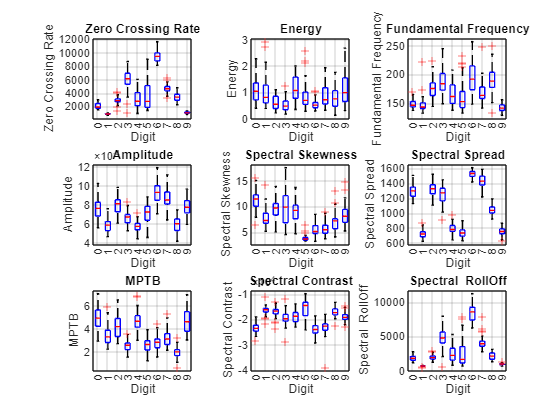

correct = 0;


Fs = 48000;
%guardar dados 
energyThreshold = 0.003; % Definição do valor de energia mínimo considerada como silencio
windowSize = round(0.0064 * Fs); % Window size of 0.0032s
noverlap = round(0.0032 * Fs); % Overlap should be half the window size
nfft = 2^nextpow2(windowSize); % Number of points for the FFT



%META 1
zeroCrossingRates = zeros(10, 50);
energy = zeros(10,50);
fundFreq = zeros(10,50);

%META 2
% Get the Matrix with the frequencies
amplitudes = getDataMatrix('0',5000);
freq = (0:4999);
% Initialize the vectors
skewnessMatrix = zeros(50,10);
spectralSpread = zeros(50,10);

%calcular
amplitudeMeans = squeeze(mean(amplitudes, 2));

%META3

meanPowerPerTimeBandPerDigit = cell(10, 1);
meanspectralContrastPerTimeBandPerDigit = cell(10, 1);
meanspectralRollOffPerTimeBandPerDigit = cell(10, 1);

totalMPTB = [];
totalspectralContrastPerTimeBand = [];
totalspectralRollOffPerTimeBand = [];

MPTBperdigit = [];
SCPTBperdigit = [];
SROPTBperdigit = [];

maxTimeWindows = 200;
maxFrequencyBands = nfft /2 +1;

MPTBperdigit = [];
SCPTBperdigit = [];
SROPTBperdigit = [];

%Loop pelos ficheiros de audio todos
for i = 0:9

    MPTBperdigit = [];
    SCPTBperdigit = [];
    SROPTBperdigit = [];


    for j = 0:49
        % Lê o ficheiro de audio
        [audioData, samplingRate] = audioread(sprintf("Audios/%d_40_%d.wav", i, j));

        trimmedAudioData = removeSilence(audioData,energyThreshold);

        audioData = removeSilence(audioData,energyThreshold);
        audioData = normalizeSignal(audioData);
        audioData = fillSilence(audioData, 0.6, samplingRate);

        prev_spectrum = abs(fft(audioData(1, :)));
        % Calculo das features

        % META 1
        energy(i+1, j+1) = sum(trimmedAudioData.^2); % Calculo da energia(Dominio discreto)
        zeroCrossingRates(i+1, j+1) = sum(abs(diff(sign(trimmedAudioData)))) / (2 * length(trimmedAudioData) / samplingRate);
        fundFreq(i+1,j+1) = mean(pitch(trimmedAudioData, samplingRate)); % Média do pitch de cada frame

        % META 2

        skewnessMatrix(j+1, i+1) = spectral_skewness(amplitudes(j+1, :, i+1));      %Spectral Skewness              
        spectralSpread(j+1, i+1) = spectral_spread(amplitudes(j+1, :, i+1), freq);


        %META 3

        [s, f, t] = spectrogram(audioData, hamming(windowSize), noverlap, nfft, Fs, 'yaxis');
        powerSpectrum = abs(s) .^ 2;
        frequencySpectrum = abs(fft(audioData));

        curMPTB = mean(powerSpectrum, 1); % Row Matrix
        curSpectralRollOffPerTimeBand = arrayfun(@(i) spectral_rolloff(powerSpectrum(:,i), samplingRate, 0.85), 1:size(powerSpectrum, 2));
        curSpectralContrastPerTimeBand = spectral_contrast(powerSpectrum, samplingRate);

        MPTB = padWithZeros(curMPTB, maxFrequencyBands);
        spectralContrastPerTimeBand= padWithZeros(curSpectralContrastPerTimeBand, maxFrequencyBands);
        spectralRollOffPerTimeBand = padWithZeros(curSpectralRollOffPerTimeBand, maxFrequencyBands);

        MPTBperdigit = [MPTBperdigit; MPTB];
        SCPTBperdigit = [SCPTBperdigit; spectralContrastPerTimeBand];
        SROPTBperdigit = [SROPTBperdigit; spectralRollOffPerTimeBand];

    end
     digitopara2dlMPTB{i+1} = MPTBperdigit;
     digitopara2dtotalspectralContrastPerTimeBand{i+1} = SCPTBperdigit;
     digitopara2dtotalspectralRollOffPerTimeBand{i+1} = SROPTBperdigit;

end

m2 = cell(10,50);
m3 = cell(10,50);
m5 = cell(10,50);



for i = 1:10
    for j = 1:50
        m2{i,j} = mean(digitopara2dlMPTB{i}(j, :));
        m3{i,j} = mean(digitopara2dtotalspectralContrastPerTimeBand{i}(j, :));
        m5{i,j} = mean(digitopara2dtotalspectralRollOffPerTimeBand{i}(j, :));
    end
end

matrices1 = {zeroCrossingRates',energy',fundFreq',amplitudeMeans,skewnessMatrix,spectralSpread, cell2mat(m2)',cell2mat(m3)',cell2mat(m5)'};
labels = {'Zero Crossing Rate', 'Energy', 'Fundamental Frequency', 'Amplitude', 'Spectral Skewness', 'Spectral Spread', 'MPTB', 'Spectral Contrast', 'Spectral  RollOff'};

plotBoxplots(matrices1, labels);






freq = (0:4999);
maxTimeWindows = 200;
maxFrequencyBands = nfft /2 +1;
for i = 0:9

    answer = i;
    
    for j = 0:49
        
        sampleZCR = 0;
        sampleEnergy = 0;
        sampleFF = 0;
        sampleAMP = 0;
        sampleSKEW = 0;
        sampleSPR = 0;
        sampleMPTB = 0;
        sampleCONT = 0;
        sampleROLL = 0;
        digitscore = zeros(1, 10);
        
        % Lê o ficheiro de audio
        [audioData, samplingRate] = audioread(sprintf("Audios/%d_40_%d.wav", i, j));

        trimmedAudioData = removeSilence(audioData,energyThreshold);

        audioData = removeSilence(audioData,energyThreshold);
        audioData = normalizeSignal(audioData);
        audioData = fillSilence(audioData, 0.6, samplingRate);


        % Calculo das features
        
        % META 1
        sampleEnergy = sum(trimmedAudioData.^2); % Calculo da energia(Dominio discreto)
        sampleZCR= sum(abs(diff(sign(trimmedAudioData)))) / (2 * length(trimmedAudioData) / samplingRate);
        sampleFF = mean(pitch(trimmedAudioData, samplingRate)); % Média do pitch de cada frame

        % META 2
            
            % Compute the Fourier transform
            X = fft(audioData);
            
            %get only the first half, since its symmetrical
            X = X(1:floor(length(X)/2));

            % Compute the absolute value of the Fourier coefficients
            X = abs(X);

            % Normalize by the number of samples (median amplitude spectre,
            % normalized by the number of samples)
            amplitude_spectrum = X / length(audioData);
            amplitude_spectrum = amplitude_spectrum(1:5000);

            % META 2

            sampleSKEW = spectral_skewness(amplitude_spectrum);      %Spectral Skewness              
            sampleSPR = spectral_spread(amplitude_spectrum, freq);      %Spectral Spread

            %sampleSPR = mean(sampleSPR);
            sampleAMP = mean(amplitude_spectrum,1);

        %META 3
       
        [s, f, t] = spectrogram(audioData, hamming(windowSize), noverlap, nfft, Fs, 'yaxis');
        powerSpectrum = abs(s) .^ 2;
        frequencySpectrum = abs(fft(audioData));

        sampleMPTB = mean(powerSpectrum, 1); % Row Matrix
        sampleROLL = arrayfun(@(i) spectral_rolloff(powerSpectrum(:,i), samplingRate, 0.85), 1:size(powerSpectrum, 2));
        sampleCONT = spectral_contrast(powerSpectrum, samplingRate);

        sampleMPTB = padWithZeros(sampleMPTB, maxFrequencyBands);
        sampleCONT= padWithZeros(sampleCONT, maxFrequencyBands);
        sampleROLL = padWithZeros(sampleROLL, maxFrequencyBands);
        
        sampleMPTB = mean(sampleMPTB);
        sampleCONT = mean(sampleCONT);
        sampleROLL = mean(sampleROLL);
        
     
    
        % ZERO CROSSING RATE
        ZCRintervals = [5302,6947;8781,9969;863,1320;2990,5083];
        closestInterval = checkIntervals(sampleZCR,ZCRintervals);
        if isequal(closestInterval, [5302,6947])
            digitscore(4) = digitscore(4) + 1;
        elseif isequal(closestInterval, [8781,9969])
            digitscore(7) = digitscore(7) + 1;
        elseif isequal(closestInterval, [863,1320])
            digitscore([2, 10]) = digitscore([2, 10]) + 1/2;
        elseif isequal(closestInterval, [2990,5083])
            digitscore([1, 3, 5, 6, 8, 9]) = digitscore([1, 3, 5, 6, 8, 9]) + 1/6;
        end


        % ENERGY
        EnergyIntervals = [0.345,0.855;0.656,1.57;0.473,1.27];
        closestInterval = checkIntervals(sampleEnergy,EnergyIntervals);
        if isequal(closestInterval, [0.345,0.855])
            digitscore([3,4,7]) = digitscore([3,4,7]) + 1/3;
        elseif isequal(closestInterval, [0.656,1.57])
            digitscore([1,5,10]) = digitscore([1,5,10]) + 1/3;
        elseif isequal(closestInterval, [0.473,1.27])
            digitscore([2,6,8,9]) = digitscore([2,6,8,9]) + 1/4;
        end
        
        % FUNDAMENTAL FREQUENCY
        FFIntervals = [137,152.7;141.9,181.6;163.2,214];
        closestInterval = checkIntervals(sampleFF,FFIntervals);
        if isequal(closestInterval, [137,152.7])
            digitscore([1,2,10]) = digitscore([1,2,10]) + 1/3;
        elseif isequal(closestInterval, [141.9,181.6])
            digitscore([5,6,8]) = digitscore([5,6,8]) + 1/3;
        elseif isequal(closestInterval, [163.2,214])
            digitscore([3,4,7,9]) = digitscore([3,4,7,9]) + 1/4;
        end

                % SPECTRAL MEAN
        SpectralMeanIntervals = [5.27e-4,7.4e-4;6.35e-4,8.42e-4;8.06e-4,9.99e-4];
        closestInterval = checkIntervals(sampleAMP,SpectralMeanIntervals);
        if isequal(closestInterval, [5.27e-4,7.4e-4])
            digitscore([2,5,9]) = digitscore([2,5,9]) + 1/3;
        elseif isequal(closestInterval, [6.35e-4,8.42e-4])
            digitscore([1,3,4,6,10]) = digitscore([1,3,4,6,10]) + 1/5;
        elseif isequal(closestInterval, [8.06e-4,9.99e-4])
            digitscore([7,8]) = digitscore([7,8]) + 1/2;
        end
        
        % SPECTRAL SKEWNESS
        SpectralSkewnessIntervals = [3.51,3.99;10.03,12.23;5.86,12.08;5.67,9.41;4.76,6.36];
        closestInterval = checkIntervals(sampleSKEW,SpectralSkewnessIntervals);
        if isequal(closestInterval, [3.51,3.99])
            digitscore(6) = digitscore(6) + 1;
        elseif isequal(closestInterval, [10.03,12.23])
            digitscore(1) = digitscore(1) + 0.8;
        elseif isequal(closestInterval, [5.86,12.08])
            digitscore([3,4,10]) = digitscore([3,4,10]) + 1/3;
        elseif isequal(closestInterval, [5.67,9.41])
            digitscore([2,9]) = digitscore([2,9]) + 1/2;
        elseif isequal(closestInterval, [4.76,6.36])
            digitscore([7,8]) = digitscore([7,8]) + 1/2;
        end
        
        % SPECTRAL SPREAD
        SpectralSpreadIntervals = [1164,1380;1376,1559;1000,1081;680,831];
        closestInterval = checkIntervals(sampleSPR,SpectralSpreadIntervals);
        if isequal(closestInterval, [1164,1380])
            digitscore([1,3,4]) = digitscore([1,3,4]) + 1/3;
        elseif isequal(closestInterval, [1376,1559])
            digitscore([7,8]) = digitscore([7,8]) + 1/2;
        elseif isequal(closestInterval, [1000,1081])
            digitscore(9) = digitscore(9) + 1;
        elseif isequal(closestInterval, [680,831])
            digitscore([2,5,10]) = digitscore([2,5,10]) + 1/3;
        end
        
        % MPTB
        MPTBIntervals = [1.64,2.17;3.32,5.67;2.13,3.57;2.62,3.86];
        closestInterval = checkIntervals(sampleMPTB,MPTBIntervals);
        if isequal(closestInterval, [1.64,2.17])
            digitscore(9) = digitscore(9) + 1;
        elseif isequal(closestInterval, [3.32,5.67])
            digitscore([1,3,5,10]) = digitscore([1,3,5,10]) + 1/4;
        elseif isequal(closestInterval, [2.13,3.57])
            digitscore([4,6,7,8]) = digitscore([4,6,7,8]) + 1/4;
        elseif isequal(closestInterval, [2.62,3.86])
            digitscore([2,8]) = digitscore([2,8]) + 1/2;
        end
        
        % SPECTRAL CONTRAST
        SpectralContrastIntervals = [-25352,-21782;-18541,-13217;-20888,-17266];
        closestInterval = checkIntervals(sampleCONT,SpectralContrastIntervals);
        if isequal(closestInterval, [-25352,-21782])
            digitscore([1,7,8]) = digitscore([1,7,8]) + 1/3;
        elseif isequal(closestInterval, [-18541,-13217])
            digitscore([2,3,6,9]) = digitscore([2,3,6,9]) + 1/4;
        elseif isequal(closestInterval, [-20888,-17266])
            digitscore([4,5,10]) = digitscore([4,5,10]) + 1/3;
        end
        
        % SPECTRAL ROLL OFF
        SpectralRollOffIntervals = [3557,7950;7387,9260;500,1010;1110,3508];
        closestInterval = checkIntervals(sampleROLL,SpectralRollOffIntervals);
        if isequal(closestInterval, [3557,7950])
            digitscore([4,8]) = digitscore([4,8]) + 1/2;
        elseif isequal(closestInterval, [7387,9260])
            digitscore(7) = digitscore(7) + 1;
        elseif isequal(closestInterval, [500,1010])
            digitscore([2,10]) = digitscore([2,10]) + 1/2;
        elseif isequal(closestInterval, [1110,3508])
            digitscore([1,3,5,6,9]) = digitscore([1,3,5,6,9]) + 1/5;
        end


        maxValue = max(digitscore);
        maxIndices = find(digitscore == maxValue);

        randomIndex = randi(length(maxIndices));
        i;
        guess = maxIndices(randomIndex)-1;
        
        
        
        if guess == answer
            correct = correct + 1;
        end

        
    end
end



fprintf("Percentage of correct answers: %f% \n", correct/500*100);

Percentage of correct answers: 71.800000

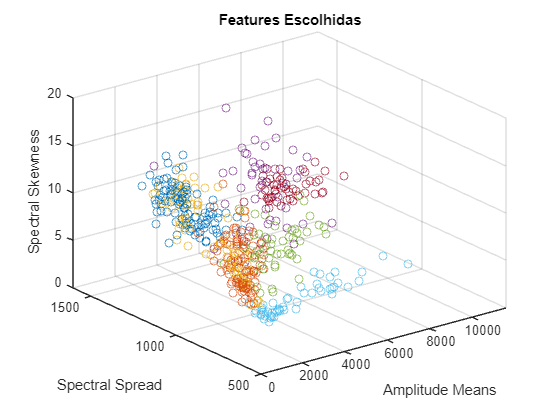

figure;
scatter3(zeroCrossingRates', spectralSpread, skewnessMatrix)
xlabel('Amplitude Means');
ylabel('Spectral Spread');
zlabel('Spectral Skewness');
title('Features Escolhidas');

function closestInterval = checkIntervals(value, intervals)
    distances = [];
    for i = 1:size(intervals, 1)
        lower = intervals(i, 1);
        upper = intervals(i, 2);
        if lower <= value && value <= upper

            distance = abs(value - lower);
    
                
            distances = [distances; distance, i];
        end
    end
    if ~isempty(distances)
        [~, idx] = min(distances(:, 1));
        closestInterval = intervals(distances(idx, 2), :);
    else
        endDistances = abs(intervals(:, 2) - value);
        [~, idx] = min(endDistances);
        closestInterval = intervals(idx, :);
    end
end
